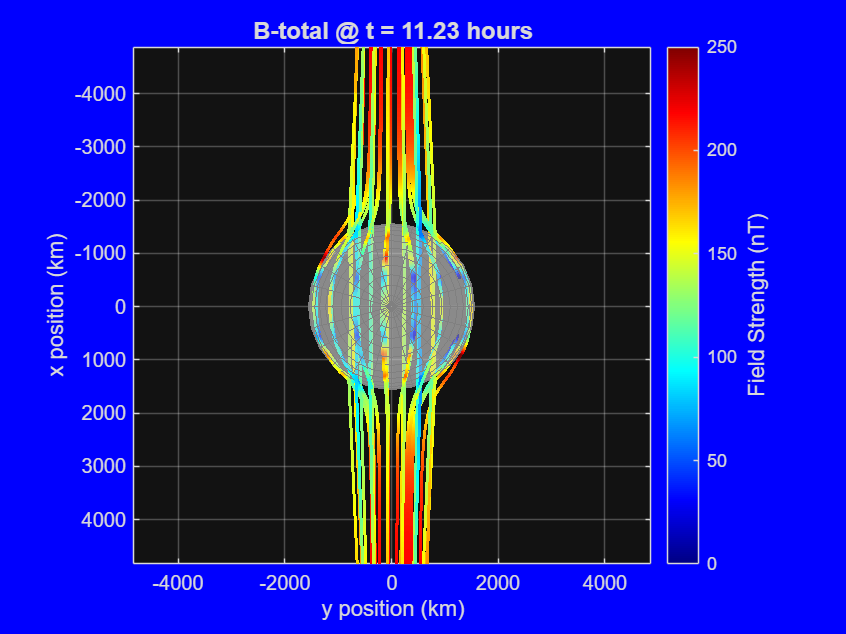

clear
% define constants

r_m = 1560; % Europa radius (km)
A = 0.95; % amplitude response factor
phi = 0.14; % phase lag in radians (around 8 deg)
synodic_period = 11.23 * 3600; % 11.23 hr period
omega = 2*pi / (synodic_period); % synodic freq. (rad/sec), 


% elliptical primary field amplitudes 
% Br oscillates 200-250nT, Bphi oscillates 60-75nT @ Europa
% using separate x/y amplitudes make the primary field elliptically
% polarized instead of circularly polarized
Bprim_x_amp = 225; % midpoint of zimmer's range
Bprim_y_amp = 67;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% create spatial grid 
grid_limit = 7 * r_m; % view up to 7 planetary radii out 
[X,Y,Z] = meshgrid(linspace(-grid_limit, grid_limit, 60), ...
    linspace(-grid_limit,grid_limit, 60), ...
    linspace(-grid_limit, grid_limit, 60));

R = sqrt(X.^2 + Y.^2 + Z.^2);
mask = R >= r_m; 

% set up animation time array (60 steps over one full period)
num_frames = 60;
time_steps = linspace(0, synodic_period, num_frames);

% create figure once outside the loop
fig = figure('Color', 'b');
set(gcf, 'Position', [100, 100, 800, 600]);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



% animation loop 
for t = time_steps

    r_dot_e0x = X; % e0x = [1;0;0] so r.e0x = X
    r_dot_e0y = Y; % e0x = [1;0;0] so r.e0y = Y

    % complex secondary field: x-driven 
    coefx_c = -(A * Bprim_x_amp * r_m^3) .* exp(-1i*(omega * t - phi)) ./ (2 * R.^5);
    Bsecx_x = coefx_c .* (3 * r_dot_e0x .*X - R.^2);
    Bsecx_y = coefx_c .* (3 * r_dot_e0x .*Y);
    Bsecx_z = coefx_c .* (3 * r_dot_e0x .*Z);

    % complex secondary field: y-driven (90 deg / pi/2 shifted)
    coefy_c = -(A * Bprim_y_amp * r_m^3) .* exp(-1i*(omega*t - pi/2 - phi)) ./ (2 * R.^5);
    Bsecy_x = coefy_c .* (3*r_dot_e0y.*X);
    Bsecy_y = coefy_c .* (3*r_dot_e0y.*Y - R.^2);
    Bsecy_z = coefy_c .* (3*r_dot_e0y.*Z);

    % complex primary field
    Bprim_c_x = Bprim_x_amp * exp(-1i*omega*t);
    Bprim_c_y = Bprim_y_amp * exp(-1i*(omega*t - pi/2));

    % sum as complex, take the real part exactly once
    Bx = real(Bsecx_x + Bsecy_x + Bprim_c_x);
    By = real(Bsecx_y + Bsecy_y + Bprim_c_y);
    Bz = real(Bsecx_z + Bsecy_z);   % Bprim has no z-component

    Bx(~mask) = 0;
    By(~mask) = 0;
    Bz(~mask) = 0;





   %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


    clf; % clear figure window so frames don't overlap



    hold on;


    % draw Europa as 3d sphere
    [sx, sy, sz] = sphere(24);
    mesh(sx*r_m, sy*r_m, sz*r_m, 'FaceColor', [0.8 0.8 0.8], 'EdgeColor',[0.5 0.5 0.5]);
    alpha(0.4);

    % find current primary field direction directly from its real comps
    Bx_prim_now = real(Bprim_c_x);
    By_prim_now = real(Bprim_c_y);
    dipole_angle = atan2(By_prim_now, Bx_prim_now);

    % base ring template (orthogonal to dipole axis)
    theta = linspace(0, 2*pi, 16);
    seed_radius = 1.05 * r_m;

    % generate ring points centered around origin 
    % construct them relative to dipole axis
    local_long = seed_radius * 0.85;
    local_r = seed_radius * 0.5;

    % positive pole ring template
    x1_temp = ones(size(theta)) * local_long;
    y1_temp = local_r * cos(theta);
    z1 = local_r * sin(theta);

    % rotate template coordinated by dipole's current orientation angle
    seed_X1 = x1_temp * cos(dipole_angle) - y1_temp * sin(dipole_angle);
    seed_Y1 = x1_temp * sin(dipole_angle) + y1_temp * cos(dipole_angle);

    % negative pole ring template
    x2_temp = ones(size(theta)) * -local_long;
    y2_temp = local_r * cos(theta);
    z2 = local_r * sin(theta);

    seed_X2 = x2_temp * cos(dipole_angle) - y2_temp * sin(dipole_angle);
    seed_Y2 = x2_temp * sin(dipole_angle) + y2_temp * cos(dipole_angle);


    % combine everything into the master seed list
    seed_X = [seed_X1, seed_X2];
    seed_Y = [seed_Y1, seed_Y2];
    seed_Z = [z1, z2];

    % plot mag field vectors

    % calculate total magnetic field magnitude at every grid point
    B_mag = sqrt(Bx.^2 + By.^2 + Bz.^2);

    % get raw spatial vertices of the streamlines
    verts1 = stream3(X, Y, Z, Bx, By, Bz, seed_X(:), seed_Y(:), seed_Z(:));
    verts2 = stream3(X, Y, Z, -Bx, -By, -Bz, seed_X(:), seed_Y(:), seed_Z(:));
    all_verts = [verts1; verts2];

    % loop through each streamline and plot as colored patch
    for k = 1:numel(all_verts)
        v = all_verts{k};
        if isempty(v), continue; end

        % interpolate the field strength at each vertex along specific line
        line_colors = interp3(X, Y, Z, B_mag, v(:,1), v(:,2), v(:,3));

        % create multicolored line using patch
        patch('XData', v(:,1), 'YData', v(:,2), 'ZData', v(:,3), ...
            'FaceColor', 'none', 'EdgeColor', 'interp', ...
            'CData', line_colors, 'LineWidth', 1.5);

    end

    % apply colormap and colorbar scaling
    colormap(jet); % 'jet' or 'turbo' goes from blue (low) to red (high)
    c = colorbar;
    ylabel(c, 'Field Strength (nT)', 'FontSize', 11);

    % set color limits: because B drops off like 1/r^5, capping the max color 
  
    clim([0, 250]);



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


    % grid formatting
    axis equal; 
    xlim([-grid_limit, grid_limit]);
    ylim([-grid_limit, grid_limit]);
    zlim([-grid_limit, grid_limit]);
    xlabel('x position (km)', 'FontSize', 11);
    ylabel('y position (km)', 'FontSize', 11);
    zlabel('z position (km)', 'FontSize', 11);

    % display current time in hours on the title
    title(sprintf('B-total @ t = %.2f hours', t/3600), 'FontSize', 12);
    grid on;
    box on;

    xlim([-4875 4832])
    ylim([-4835 4872])
    zlim([-4853 4853])


    view([-270 90])

    


    drawnow; % force matlab to draw graphics pipeline immediately
    pause(0.05); % execution speed

end